# Streaming with Pluto

Summary of example objective

% Setup environment
plutoradiosetup;


You must set up the system environment in each MATLAB session to use 
Communications System Toolbox Support Package for ADALM-PLUTO Radio. 
As a convenience, this has been done for this session. You can automate 
this step for future sessions by calling plutoradiosetup() in your 
startup.m file.

If you have not set up the host and SDR hardware for proper communication
then create an sdrdev object and call thelaunchSetupWizard method.

For more help, use help plutoradio, or see the full documentation.



## Setup radios and TX signal

% Send some data back and forth
filt = comm.RaisedCosineTransmitFilter('RolloffFactor',0.5);
preamble = repmat(randi([0 3],10,1),10,1);
signal = filt(pskmod([preamble;randi([0 3],2^15,1)],4,pi/4));
frames = 10;

% Create some objects
rx = sdrrx('Pluto','SamplesPerFrame',length(signal),'OutputDataType','double');
tx = sdrtx('Pluto','Gain',-20);
rx.CenterFrequency = tx.CenterFrequency + 1e3;


## Receiver and transmit alternating

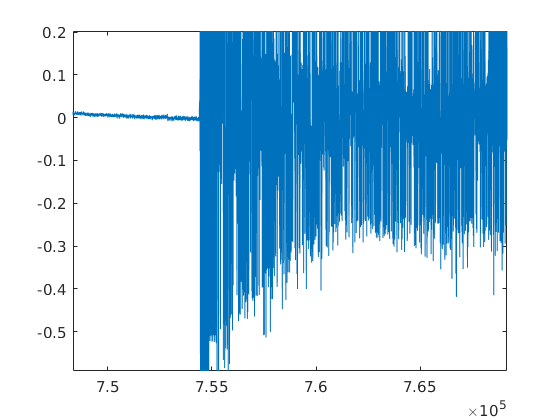

y = zeros(rx.SamplesPerFrame,frames);
for n = 1:frames
    tx(signal);
    y(:,n) = rx();
end
figure;plot(real(reshape(y,numel(y),1)));

## Try another AGC setting

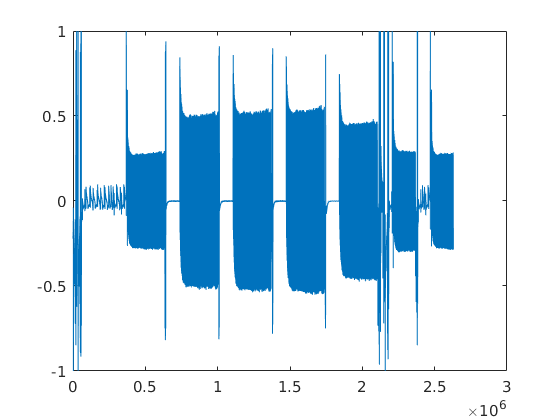

rx = sdrrx('Pluto','SamplesPerFrame',length(signal),'OutputDataType','double','GainSource','AGC Fast Attack');
y = zeros(rx.SamplesPerFrame,frames);
for n = 1:frames
    tx(signal);
    y(:,n) = rx();
end
figure;plot(real(reshape(y,numel(y),1)));

## Transmit continuous and then receive

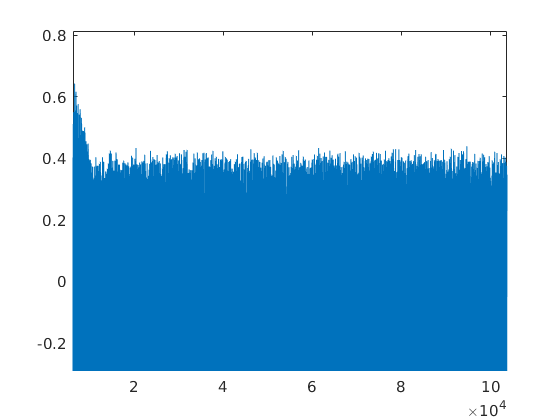

y = zeros(rx.SamplesPerFrame,frames);
tx.transmitRepeat(signal);
for n = 1:frames
    y(:,n) = rx();
end
r = reshape(y,numel(y),1);
figure;plot(real(r));

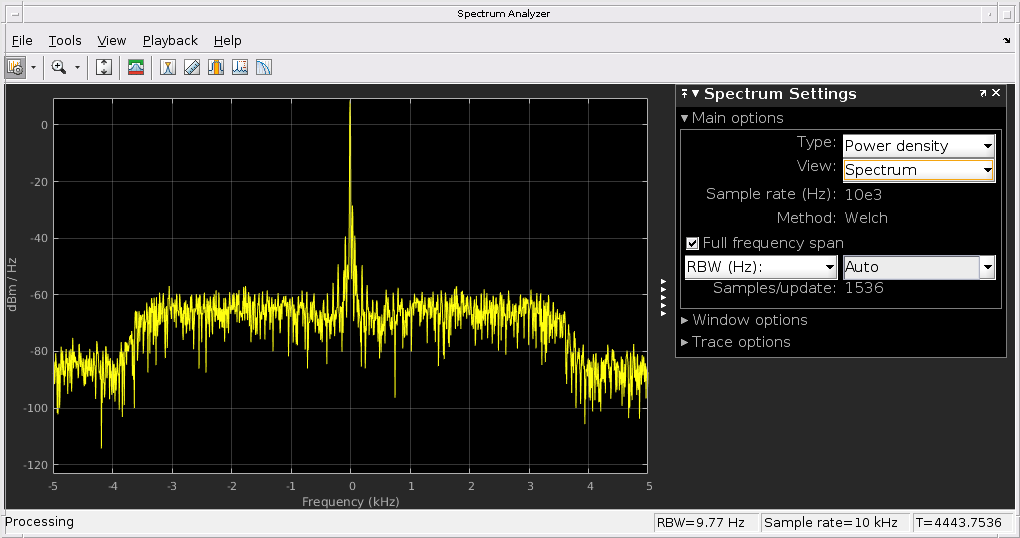

% sa = dsp.SpectrumAnalyzer;
% for n=1:frames
%     sa(y(:,n));
%     pause(0.5)
% end
for n = 1:50
    sa(rx());
end

## Save to file

bbw = comm.BasebandFileWriter('myIQ.bb');
bbw(r);
bbw.release(); % write file


## Read data from file

bbr = comm.BasebandFileReader('myIQ.bb','SamplesPerFrame',2622240);
r = bbr();
size(r)

ans =      2622240           1


## Recover

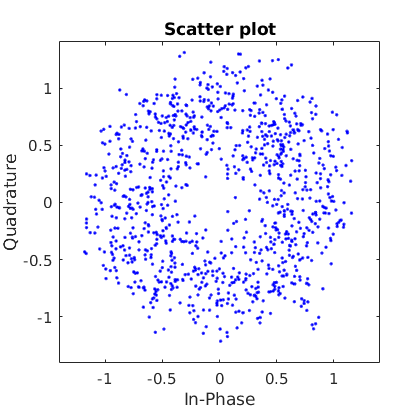



filtRX = comm.RaisedCosineReceiveFilter('DecimationFactor',4);
rFiltered = filtRX(r);
scatterplot(rFiltered(end-1024:end))

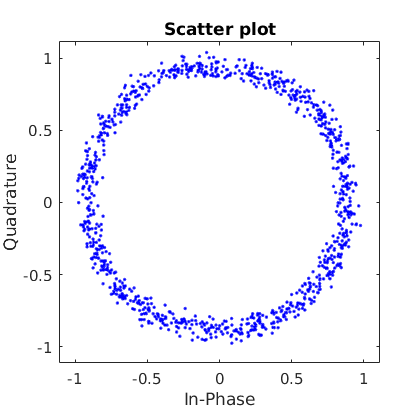

ss = comm.SymbolSynchronizer('TimingErrorDetector','Gardner (non-data-aided)','SamplesPerSymbol',2,...
    'NormalizedLoopBandwidth',0.001,'DampingFactor',4);
rTimed = ss(rFiltered);
scatterplot(rTimed(end-1024:end))

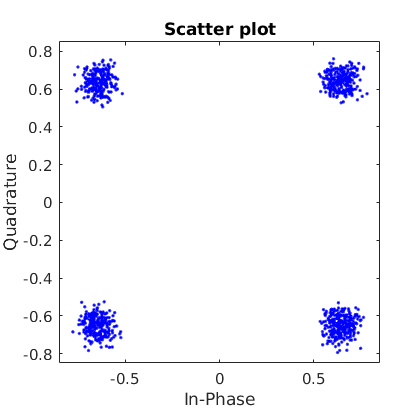

cs = comm.CarrierSynchronizer('Modulation','QPSK','SamplesPerSymbol',1);
rSynced = cs(rTimed);
scatterplot(rSynced(end-1024:end))

## Find frame starts

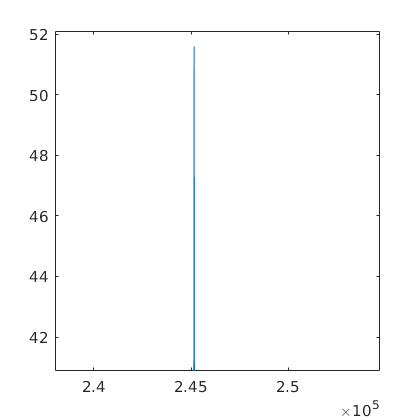


corr = abs(filter(pskmod(preamble(end:-1:1),4,pi/4),1,rSynced(1e3:end)));
plot(corr)

sum(corr>=max(corr)*.8)

ans = 30